This code generates a .blk file for creating a profile commad that ensures a constant strainrate in the sample

First we need to generate the point where the maching should be at a certain time. For this code we will divied the curve into 100 linear segments. For the strainrate to be constant in a uniaxial test (neglecting the egde effect) the movment of the piston need to follow


$$x(t)=L\left(\mathrm{e}^{\dot{\epsilon} \cdot t}-1\right)$$


where L is the intial lenght and epsilon_dot is the strainrate of the sample

the total time for the test to complet is found by 


$$t_{end} =\frac{\ln \left(\frac{L+x_{\text {end }}}{L}\right)}{\dot{\epsilon}}$$


where x_end is the total trave of the machine. setting the requred strain rate, and the intial lenght we will find the final time and calculate the positions at those times and the times step size. space the strainrate in an log space is expected give better results, here is the logspace of 0.01 to 0.1: below the plot of the profile cen be see


L = 0.054;      % [m]
e_dot = 0.09 ;
x_end = 0.240;  %[m]
nsteps = 100;

%calc total time and time step
t_tot = log((L+x_end)/L)/e_dot

t_tot =   18.828841341937860


dt = t_tot/nsteps

dt =    0.188288413419379


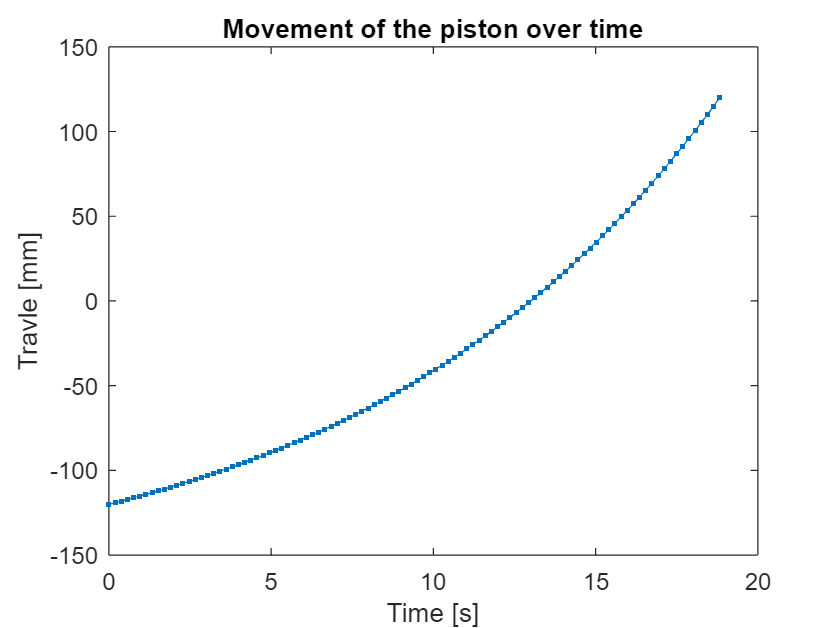


timesteps = linspace(0, t_tot,nsteps);

%calc locations
x = L*(exp(e_dot*timesteps)-1);

%convert to mm and the maching coords
x = x*1000 - 120;

%plotting
plot(timesteps,x,'.-')
title('Movement of the piston over time')
xlabel('Time [s]')
ylabel('Travle [mm]')

In order to impliment strain hold we have defind 3 location where the displacment will be held constant. This is done with in MTS and therefor we will now create a sereis of files for each of the 3 holds.

File "Strainrate_0.0010_step_1.blk" has been created.
File "Strainrate_0.0010_step_2.blk" has been created.
File "Strainrate_0.0010_step_3.blk" has been created.
File "Strainrate_0.0010_step_4.blk" has been created.


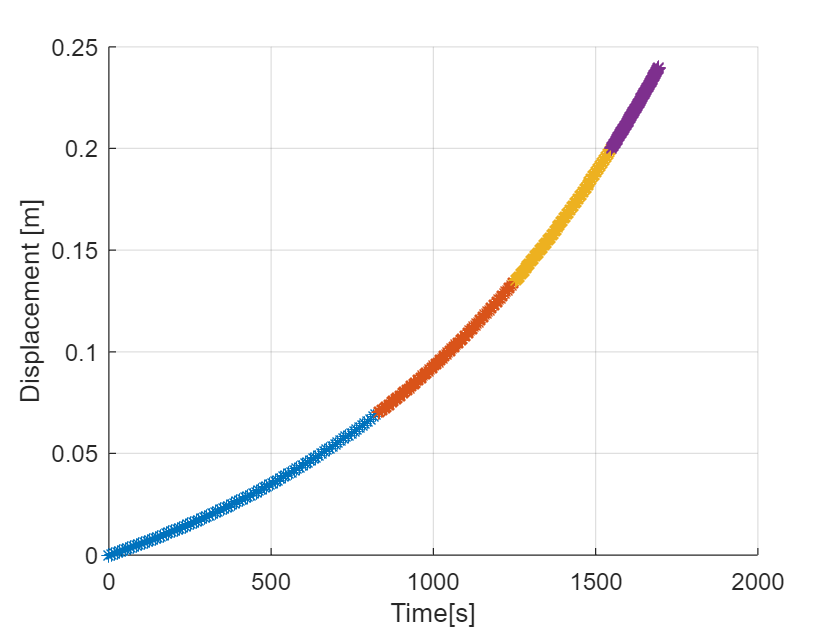

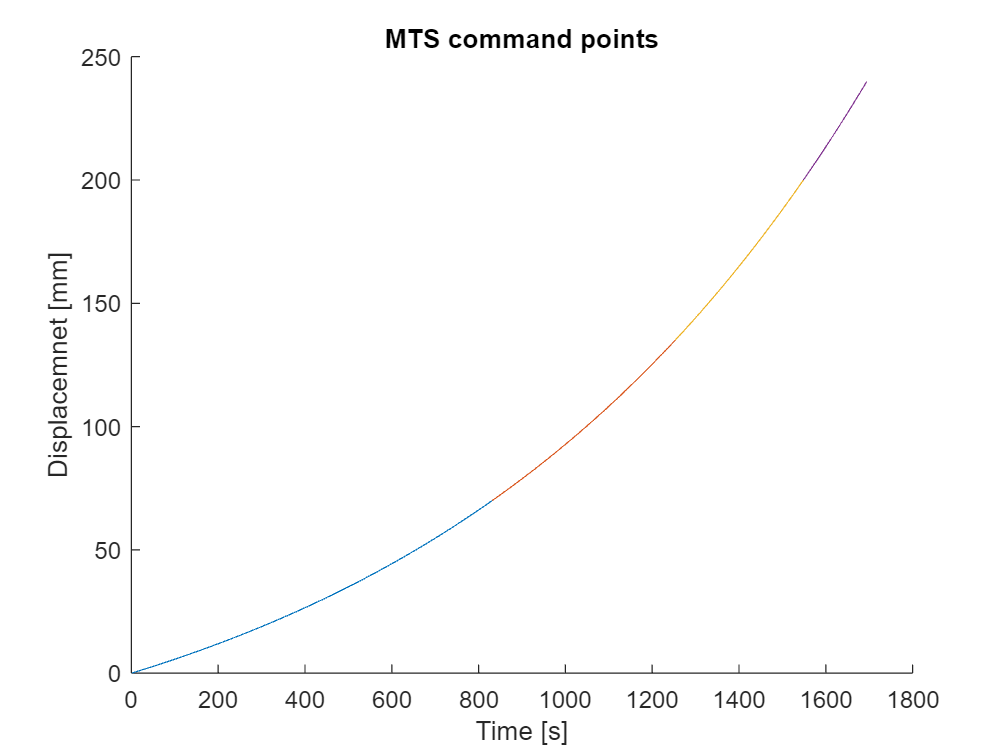

clear all
close all



e_dot = 0.001;       % Strainrate
nsteps = 100;       % number of linear segments
L_0 = 0.054;        % [m]
L = L_0;
t_tot = 0;
t_old = 0;
x_old = 0;
holdDisplacments = [0 70 135 200 240]/1000; %[m]



for i = 1:(numel(holdDisplacments)-1)
    x_end = holdDisplacments(i+1) - holdDisplacments(i);
    %calc total time of the step and time step size
    t_end = log((L+x_end)/L)/e_dot;
    t_tot = t_tot + t_end + 60;
    timesteps = linspace(0, t_end,nsteps);
    dt = t_end/nsteps;
    
    %calc locations
    x = L*(exp(e_dot*timesteps)-1);

    figure(1)
    hold on
    grid on
    plot(timesteps+t_old,x+x_old,'*-')
    xlabel('Time[s]')
    ylabel('Displacement [m]')
    hold off

    %convert to mm maching coords for the DTU setup
    x_MTS = (x+x_old)*1000;

    figure(2)
    hold on
    plot(timesteps+t_old,x_MTS)
    xlabel('Time [s]')
    ylabel('Displacemnet [mm]')
    title('MTS command points')
    hold off

    % Update the starting point and internal vars
    L = L_0 + holdDisplacments(i+1);
    x_old = x(end) + x_old;
    t_old = timesteps(end) + t_old;


    % Define the header information
    header = {
        'Filetype= Block-Arbitrary'
        'Channels= 1'
        'Channel(1)= Ch 1'
        sprintf('Time= %.5f sec',dt)
        'Shape= Ramp'
        'Level1'
        'mm'
        };


    % Specify the file name
    file_name = sprintf('Strainrate_%.4f_step_%d.blk',e_dot,i);

    % Open the file for writing
    fileID = fopen(file_name, 'w');

    % Write the header to the file
    for i = 1:numel(header)
        fprintf(fileID, '%s\n', header{i});
    end

    % Write the pathlocations array to the file
    fprintf(fileID, '%.6f\n', x_MTS);

    % Close the file
    fclose(fileID);

    disp(['File "', file_name, '" has been created.']);
end

t_tot = t_tot-60;
fprintf('Total time of test is %f [mim]\n',t_tot/60)

Total time of test is 31.243262 [mim]
